clear

data = readtable("calib_data_full_rot.csv", "VariableNamingRule","preserve")

data = 574×10 table
    Var1      accX         accY        accZ       gyroX      gyroY      gyroZ      magX       magY       magZ  
    ____    _________    _________    _______    _______    _______    _______    _______    _______    _______

      0      0.093304    -0.037565    0.99426    -5.6599     -10.25    -5.3884    -12.961    -1.8146    -43.795
      1        0.1373    -0.027565    0.99826    -5.5859    -11.404    -3.5474    -12.961    -1.8146    -43.795
      2        0.1373    -0.027565    0.99826    -5.5859    -11.404    -3.5474    -11.931    -2.0963    -43.192
      3      0.053304    -0.033565     1.0963    -4.0589    -1.6885     6.4316 

collected = readtable("collected_data_full_rot.csv", "VariableNamingRule","preserve")

collected = 574×13 table
    Var1     accX      accY     accZ       gyroX        gyroY        gyroZ       magX       magY       magZ        roll       pitch        yaw   
    ____    _______    _____    _____    _________    _________    _________    _______    _______    _______    ________    ________    ________

      0     0.91532    1.347    1.347    -0.098784    -0.097493    -0.097493    -12.961    -12.961    -11.931    -0.21317    -0.36199    -0.23495
      1     0.91532    1.347    1.347    -0.098784    -0.097493    -0.097493    -12.961    -12

% figure()
% plot(data.magX, data.magY, '.');
% figure()
% plot(collected.roll, collected.pitch, 'x')

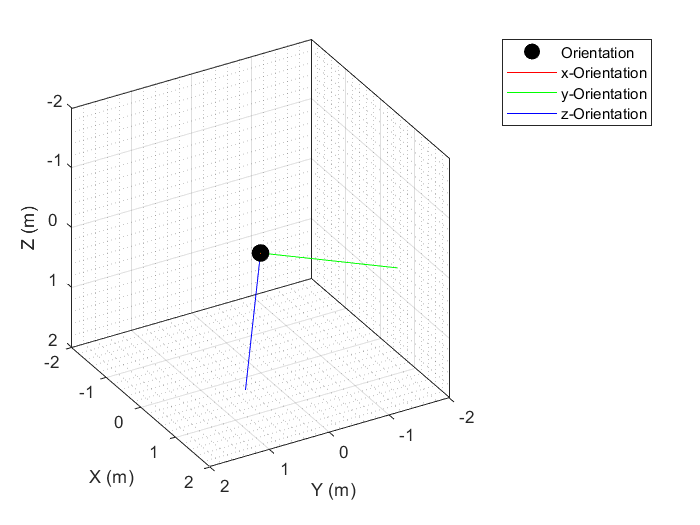

Index exceeds the number of array elements (574).

Error in tabular/dotParenReference (line 114)
        b = b(rowIndices);

figure()

tp = theaterPlot('XLimit',[-2 2],'YLimit',[-2 2],'ZLimit',[-2 2]);
op = orientationPlotter(tp,'DisplayName','Orientation',...
    'LocalAxesLength',2);

for i=1:numel(collected)
    plotOrientation(op, collected.roll(i), collected.pitch(i), collected.yaw(i))
    drawnow
end

figure(1)
subplot(3,1,1)
plot(data.accX, '.')
title("roll")

subplot(3,1,2)
plot(data.accY, '.')
title('pitch')

subplot(3,1,3)
plot(data.accZ, '.')
title("yaw")

figure(2)
subplot(3,1,1)
plot(collected.roll, '.')
title("roll")

subplot(3,1,2)
plot(collected.pitch, '.')
title('pitch')

subplot(3,1,3)
plot(collected.yaw, '.')
title("yaw")